**1- Create the Robot Model**

a) Create a Rigid Body Tree for Gen3 robot, set the home configuration and calculate the transformation at the home configuration:

gen3 = loadrobot("kinovaGen3");
gen3.DataFormat = 'column';
q_home =[0 15 180 -130 0 55 90]'*pi/180;
eeName = 'EndEffector_Link';
T_home = getTransform(gen3, q_home, eeName);

b) Visualize the robot at home configuration

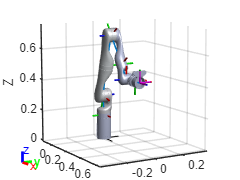

show(gen3,q_home);
axis auto;
view([60,10]); 

**2-Create Inverse Kinematics Solver and Set Parameters**

a) The [inverseKinematics](https://www.mathworks.com/help/robotics/ref/inversekinematics-system-object.html) System object creates an inverse kinematic (IK) solver to calculate joint configurations for a desired end-effector pose based on a specified rigid body tree model.

ik = inverseKinematics('RigidBodyTree', gen3);

b) Disable random restarts for inverse kinematic solver. AllowRandomRestart parameter indicates if random restarts are allowed. Random restarts are triggered when the algorithm approaches a solution that does not satisfy the constraints. A randomly generated initial guess is used.

ik.SolverParameters.AllowRandomRestart = false;

c) Specify weight priorities for pose tolerances, as a six-element vector. The first three elements correspond to the weights on the error in orientation for the desired pose. The last three elements correspond to the weights on the error in xyz position for the desired pose.

weights = [1, 1, 1, 1, 1, 1];

d) Since the desired trajectory is selected to start near the home position, define initial guess for solver as the home position of the robot.

q_init = q_home;

**3- Define Waypoints from the Desired Trajectory**

**This section helps you is to create a circular trajectory for the end effector to track.**

a) Keep the orientation of the end effector as constant for the whole range of motion. Define center and radius of the circular trajectory.

center = [0.5 0 0.4]; %[x y z]
radius = 0.1;

b) Define total time and time step, and based on that generate waypoints for the circular trajectory

dt = 0.25;
t = (0:dt:10)';
theta = t*(2*pi/t(end))-(pi/2);
points = center + radius*[0*ones(size(theta)) cos(theta) sin(theta)];

c) Plot the waypoints along with the robot at home configuration

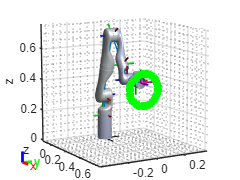

hold on;
plot3(points(:,1),points(:,2),points(:,3),'-*g', 'LineWidth', 1.5);
xlabel('x');
ylabel('y');
zlabel('z');
axis auto;
view([60,10]);
grid('minor');

**4- Solve the Inverse Kinematics for Each Waypoint**

The inverse kinematics solver finds a joint configuration that achieves the specified end-effector pose. 

a) Specify an initial guess for the configuration

b)the desired weights on the tolerances for the six components of pose. 

The inverse kinematics solver returns information about its convergence and it is recommended to check the status of the solution.

**This section helps you to find a joint configuration for a fixed end effector orientation and variable position defined by waypoints calculated in the previous sections.**

**The current solution is used as the initial guess for the next waypoint to ensure smooth and continuous trajectory. Uncomment the display command to see the status of each inverse kinematics iteration.**

numJoints = size(q_home,1);   
numWaypoints = size(points,1);
qs = zeros(numWaypoints,numJoints);
for i = 1:numWaypoints
    T_des = T_home;
    T_des(1:3,4) = points(i,:)';
    [q_sol, q_info] = ik(eeName, T_des, weights, q_init);
    
    % Display status of ik result
    %disp(q_info.Status);
    
    % Store the configuration
    qs(i,:) = q_sol(1:numJoints); 
    
    % Start from prior solution
    q_init = q_sol;
end

**5- Visualize the Animation of the Solution**

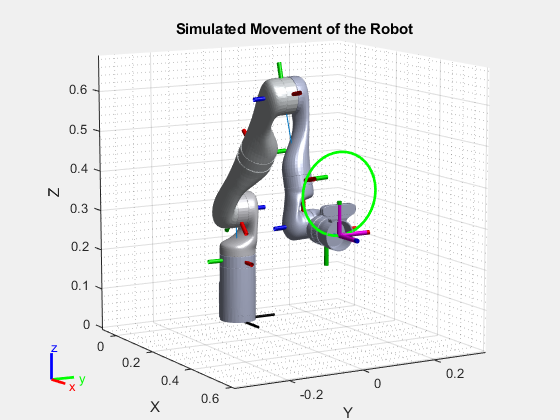

figure; set(gcf,'Visible','on');
ax = show(gen3,qs(1,:)');
ax.CameraPositionMode='auto';
hold on;
 
% Plot waypoints
plot3(points(:,1),points(:,2),points(:,3),'-g','LineWidth',2);
axis auto;
view([60,10]);
grid('minor');
hold on;
 
title('Simulated Movement of the Robot');
% Animate
framesPerSecond = 30;
r = robotics.Rate(framesPerSecond);
for i = 1:numWaypoints
    show(gen3, qs(i,:)','PreservePlot',false);
    drawnow;
    waitfor(r);
end